clear;
clc;
% read the data table from file
table = readtable('energy.csv');
% convert data table to array
data = table2array(table);
table

table = 768×10 table
     X1      X2       X3        X4      X5    X6    X7    X8     Y1       Y2  
    ____    _____    _____    ______    __    __    __    __    _____    _____

    0.98    514.5      294    110.25    7     2     0     0     15.55    21.33
    0.98    514.5      294    110.25    7     3     0     0     15.55    21.33
    0.98    514.5      294    110.25    7     4     0     0     15.55    21.33
    0.98    514.5      294    110.25    7     5     0     0     15.55    21.33
     0.9    563.5    318.5     122.5    7     2     0     0     20.84    28.28
     0.9    563.5    318.5     122.5    7     3     0     0     21.46    25.38
     0

% split data into training and validation sets
% train
train_in = data(1:700,1:8);
train_out1 = data(1:700,9);
train_out2 = data(1:700,10);
% test
test_in = data(701:768,1:8);
test_out1 = data(701:768,9);
test_out2 = data(701:768,10);

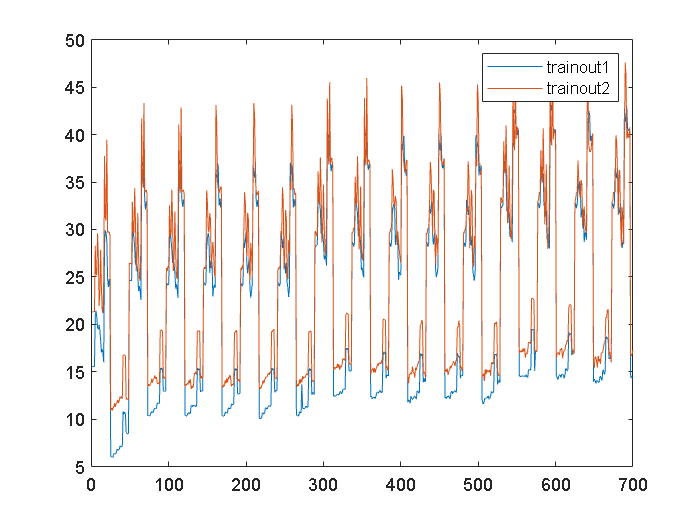

% plot input and output training data
plot(train_out1)
hold on
plot(train_out2)
legend('trainout1','trainout2');
hold off

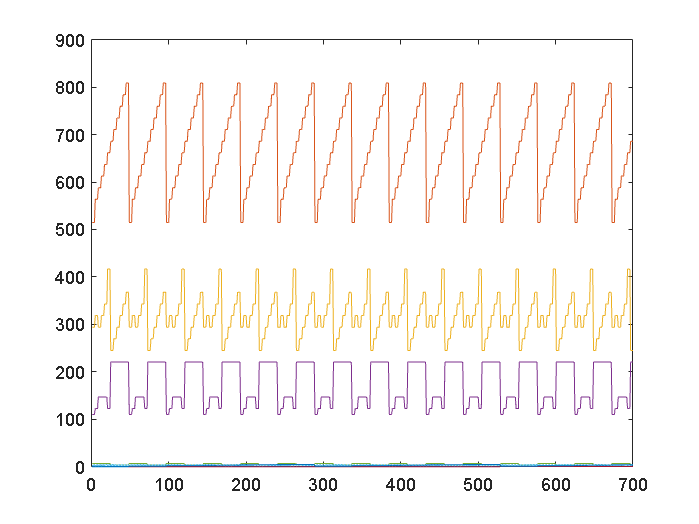

plot(train_in)

% generate sugeno fis
fis1 = genfis(train_in,train_out1)

fis1 =   sugfis with properties:

                       Name: "fis"
                  AndMethod: "prod"
                   OrMethod: "max"
          ImplicationMethod: "prod"
          AggregationMethod: "sum"
      DefuzzificationMethod: "wtaver"
    DisableStructuralChecks: 0
                     Inputs: [1×8 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [1×256 fisrule]

	See 'getTunableSettings' method for parameter optimization.


fis2 = genfis(train_in,train_out2)

fis2 =   sugfis with properties:

                       Name: "fis"
                  AndMethod: "prod"
                   OrMethod: "max"
          ImplicationMethod: "prod"
          AggregationMethod: "sum"
      DefuzzificationMethod: "wtaver"
    DisableStructuralChecks: 0
                     Inputs: [1×8 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [1×256 fisrule]

	See 'getTunableSettings' method for parameter optimization.


% setting initial fis
opt1 = anfisOptions('InitialFIS',fis1,'EpochNumber',5);
opt2 = anfisOptions('InitialFIS',fis2,'EpochNumber',5);
% tune fis
fis1 = anfis([train_in train_out1],opt1)

ANFIS info:
	Number of nodes: 555
	Number of linear parameters: 2304
	Number of nonlinear parameters: 48
	Total number of parameters: 2352
	Number of training data pairs: 700
	Number of checking data pairs: 0
	Number of fuzzy rules: 256



Start training ANFIS ...

1 	 0.238602
2 	 0.237863
3 	 0.237011
4 	 0.236058
Step size increases to 0.011000 after epoch 5.
5 	 0.234926

Designated epoch number reached. ANFIS training completed at epoch 5.

Minimal training RMSE = 0.234926


fis1 =   sugfis with properties:

                       Name: "fis"
                  AndMethod: "prod"
                   OrMethod: "max"
          ImplicationMethod: "prod"
          AggregationMethod: "sum"
      DefuzzificationMethod: "wtaver"
    DisableStructuralChecks: 0
                     Inputs: [1×8 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [1×256 fisrule]

	See 'getTunableSettings' method for parameter optimization.


fis2 = anfis([train_in train_out2],opt2)

ANFIS info:
	Number of nodes: 555
	Number of linear parameters: 2304
	Number of nonlinear parameters: 48
	Total number of parameters: 2352
	Number of training data pairs: 700
	Number of checking data pairs: 0
	Number of fuzzy rules: 256



Start training ANFIS ...

1 	 0.673007
2 	 0.670924
3 	 0.668825
4 	 0.666658
Step size increases to 0.011000 after epoch 5.
5 	 0.664464

Designated epoch number reached. ANFIS training completed at epoch 5.

Minimal training RMSE = 0.664464


fis2 =   sugfis with properties:

                       Name: "fis"
                  AndMethod: "prod"
                   OrMethod: "max"
          ImplicationMethod: "prod"
          AggregationMethod: "sum"
      DefuzzificationMethod: "wtaver"
    DisableStructuralChecks: 0
                     Inputs: [1×8 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [1×256 fisrule]

	See 'getTunableSettings' method for parameter optimization.


% y1 and y2 are test results
y1 = evalfis(fis1,test_in);
y2 = evalfis(fis2,test_in);
% calculate error for both outputs
error1 = test_out1-y1

error1 =     0.5095
    0.6586
    0.7156
    1.3587
    0.3312
    0.4195
    0.4673
    0.6638
    0.4102
    0.3422


error2 = test_out2-y2

error2 =     0.8093
    1.5573
    0.6471
    1.5240
    0.7928
    1.1656
    0.3463
    1.0686
    0.8903
    0.7187


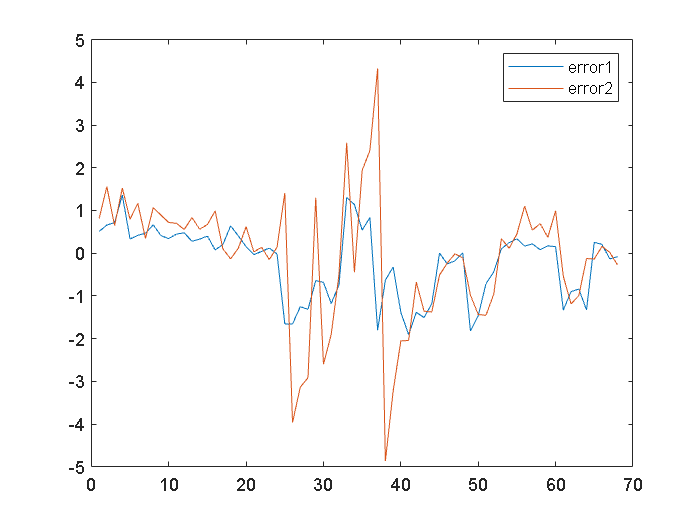

plot(error1)
hold on
plot(error2)
legend('error1','error2');
hold off

% calculate mse for each output
mse1 = mean(error1.*error1)

mse1 = 0.7055

mse2 = mean(error2.*error2)

mse2 = 2.3087

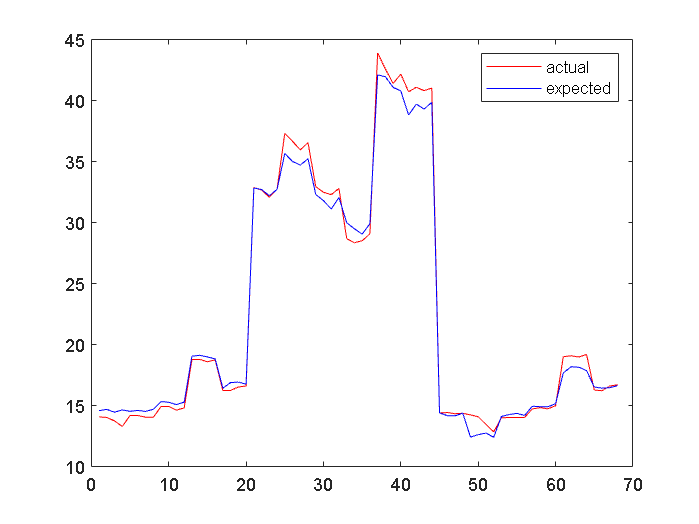

% wanted output and initial fis comparison
% for first output
plot(y1,'r')
hold on
plot(test_out1,'b')
legend('actual','expected');
hold off

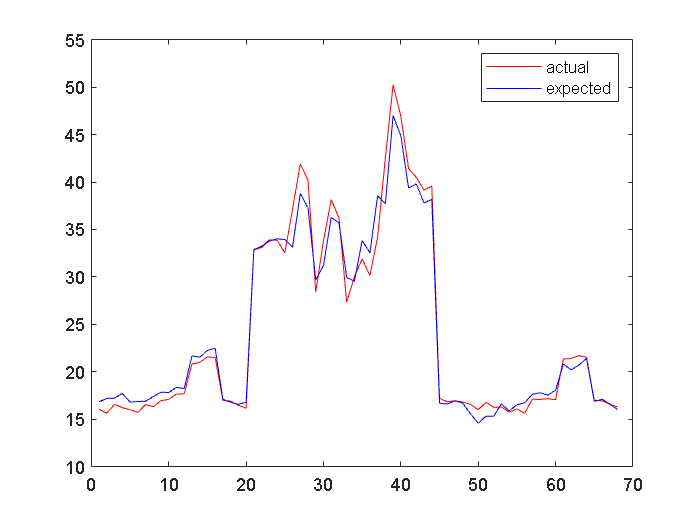

% for second output
plot(y2,'r')
hold on
plot(test_out2,'b')
legend('actual','expected');
hold off